# Resonator Modeling

Let's get back to the original question:

## Continuous Model

mdl = 'resonatorContinuous';
open_system(mdl);

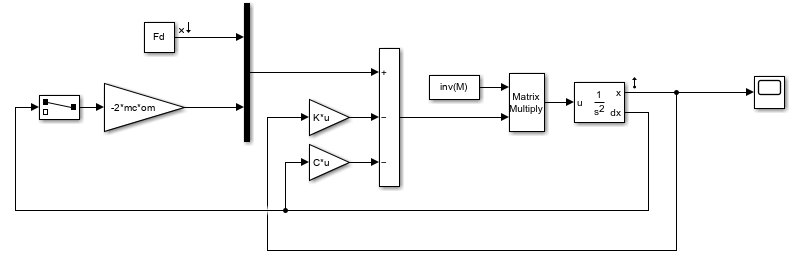

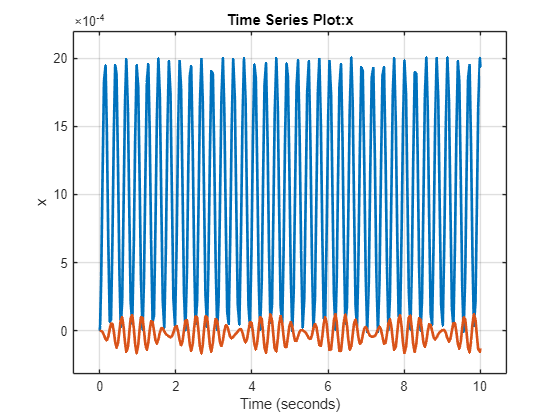

out = sim(mdl);
figure
plot(out.logsout.get('x').Values)

## Discrete Conversion

mdl = 'resonatorContinuous';
io = getlinio(mdl);
sys = linearize(mdl,io);
sysd = c2d(sys,0.01)


sysd =
 
  A = 
                  Integrator,   Integrator,   Integrator,   Integrator,
   Integrator,         0.9751    -0.0005694      0.009917    -1.906e-06
   Integrator,     -0.0006877        0.9669    -5.621e-06      0.009889
   Integrator,         -4.958       -0.1128        0.9751    -0.0005694
   Integrator,        -0.1356        -6.593     -0.001347        0.9668
 
  B = 
                          F
   Integrator,     2.49e-05
   Integrator,   -8.429e-09
   Integrator,     0.004958
   Integrator,    -2.81e-06
 
  C = 
          Integrator,   Integrator,   Integrator,   Integrator,
   x(1)             1             0             0             0
   x(2)             0             1             0             0
 
  D = 
         F
   x(1)  0
   x(2)  0
 
Sample time: 0.01 seconds
Discrete-time state-space model.


Now we can use in Simulink. This time I use State-space because of the multiple outputs.

mdl = 'resonatorDiscrete';
open_system(mdl);

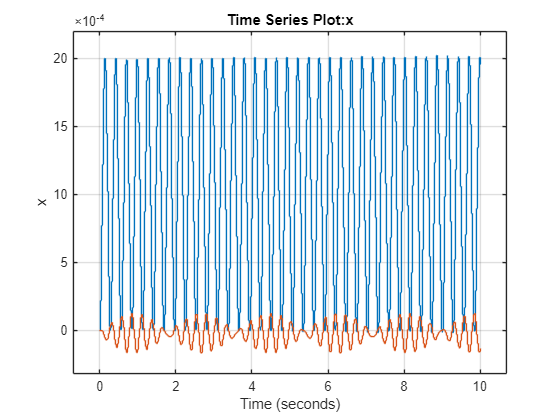

out = sim(mdl);
figure
plot(out.logsout.get('x').Values)